# XRAY CRYSTALOGRAPHY LAB

*Steven Henderson*

## Equations


$$\begin{array}{l}
\left(1\right)\;n\lambda =2\textrm{dsin}\theta_{\textrm{bragg}} \\
\left(2\right)\;d=\frac{n\lambda }{2\sin \theta_{\textrm{bragg}} }
\end{array}$$


## Introduction

In this lab we measured Bragg's angle of different crystals to determine there lattice constants and identify each crystal. The set of crystals include: NaCl, KBr, LiF, three unknown structured Si crystals, GaAs, and InP. We used a machine that shoots x-rays at the crystal and moves a gieger counter around the crystal to record a spectra of how much the x-rays were reflected at each angle.

## Pre-lab

(1)


$$\begin{array}{l}
n\lambda =2\textrm{dsin}\theta_{\textrm{bragg}} \\
d=\frac{n\lambda }{2\sin \theta_{\textrm{bragg}} }\\
\theta_{\textrm{bragg}} =\arcsin \left(\frac{n\lambda }{2d}\right)\\
\frac{\partial d}{\partial \theta_{\textrm{bragg}} }=-\frac{n\lambda \cos \theta_{\textrm{bragg}} }{2\sin^2 \theta_{\textrm{bragg}} }\cdot \partial \theta_{\textrm{bragg}} 
\end{array}$$


(2)

For (1 0 0)


$$d=a$$


For (1 1 0)


$$d=\frac{a}{\sqrt{2}}$$


For (1 1 1)


$$d=\frac{a}{\sqrt{3}}$$


% Define crystal properties
 crystals = {'NaCl', 'KBr', 'LiF', 'Si(100)', 'Si(110)', 'Si(111)', 'GaAs', 'InP'};
 lattice_constants = [5.64, 6.60, 4.03, 5.43, 5.43, 5.43, 5.653, 5.869] ; % in Å
 miller_indices = {...
    [2 0 0; 4 0 0; 6 0 0],  % NaCl
    [2 0 0; 4 0 0; 6 0 0],  % KBr
    [2 0 0; 4 0 0; 6 0 0],  % LiF
    [4 0 0; 8 0 0; 12 0 0], % Si(100)
    [2 2 0; 4 4 0; 6 6 0],  % Si(110)
    [1 1 1; 3 3 3; 4 4 4],  % Si(111)
    [4 0 0; 8 0 0; 12 0 0], % GaAs
    [2 0 0; 4 0 0; 6 0 0; 8 0 0]% InP
 };
 % Define accepted wavelengths
wavelengths = [0.6323, 0.7107] ; % Wavelenghts in Å 
bragg = [] ;
crystal = {} ;
d_arr = [] ;
a_arr = [] ;
hlk = {} ;
wavelength_arr = [] ;
n_arr = [] ;
for i = 1:length(lattice_constants)
    a = lattice_constants(i) ; % lattice constant for current crystal
    indicies = miller_indices{i} ;% miller indicies for current crystal
    for j = 1:size(indicies, 1)
        h = indicies(j, 1) ;
        n = h ;
        k = indicies(j, 2) ;
        l = indicies(j, 3) ;
        if h > 0
            h = h / h ;
        end
        if k > 0
            k = k / k ;
        end
        if l > 0
            l = l / l ;
        end                
        % get spacing
        d = a / sqrt(h^2 + k^2 + l^2) ;
        % get bragg's angle for each allowed wavelength
        for w = 1:length(wavelengths)
            lambda = wavelengths(w) ; 
            braggs = real(asind((n * lambda) / (2 * d))) ;

            bragg(end+1) = braggs ;
            crystal{end+1} = crystals{i} ;
            d_arr(end+1) = d ;
            a_arr(end+1) = a ;
            wavelength_arr(end+1) = lambda ;
            hlk{end+1} = [h k l] ;
            n_arr(end + 1) = n ;
        end
    end
end
 T = table(crystal', bragg', d_arr', a_arr', wavelength_arr', hlk', n_arr',... 
'VariableNames', {'Crystal', 'Braggs Angle', 'd', 'a', 'lambda', 'h l k', 'n'})

T = 50×7 table
    Crystal     Braggs Angle     d       a      lambda      h l k      n
    ________    ____________    ____    ____    ______    _________    _

    {'NaCl'}        6.437       5.64    5.64    0.6323    {[1 0 0]}    2
    {'NaCl'}       7.2391       5.64    5.64    0.7107    {[1 0 0]}    2
    {'NaCl'}       12.957       5.64    5.64    0.6323    {[1 0 0]}    4
    {'NaCl'}       14.597       5.64    5.64    0.7107    {[1 0 0]}    4
    {'NaCl'}       19.653       5.64    5.64    0.6323    {[1 0 0]}    6
    {'NaCl'}       22.212       5.64    5.64    0.7107    {[1 0 0]}    6
    {'KBr' }       5.4975        6.6     6.6    0.6323    {[1 0 0]}    2
    {'KBr' }       6.1817        6.6     6.6    0.7107    {[1 0 0]}    2
    {'KBr' }    

## Part 1: Data Collection

Data is read from the x-ray pparatus and imported from a .xlsx file.

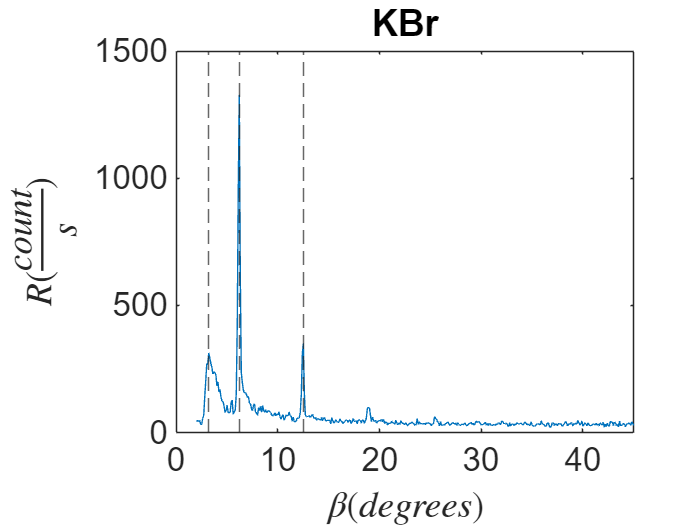

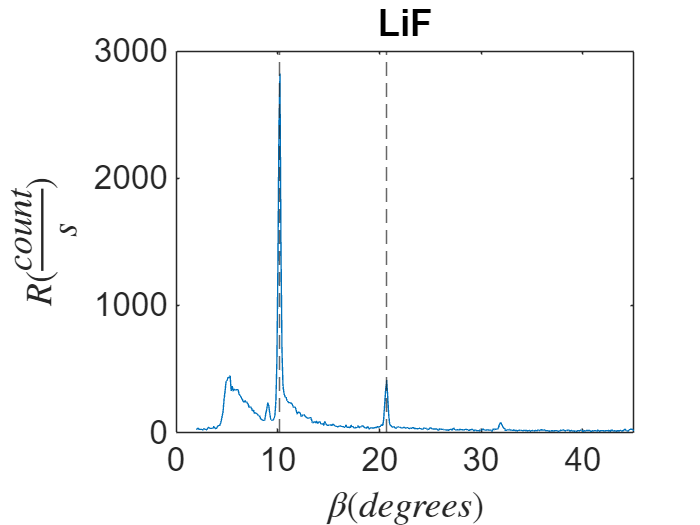

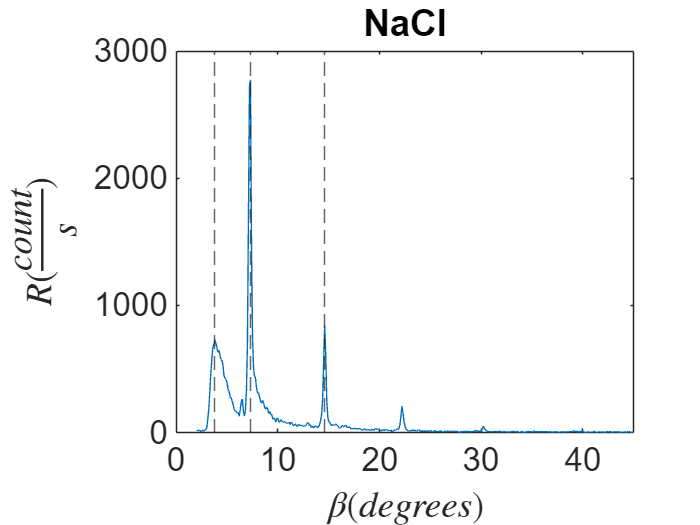

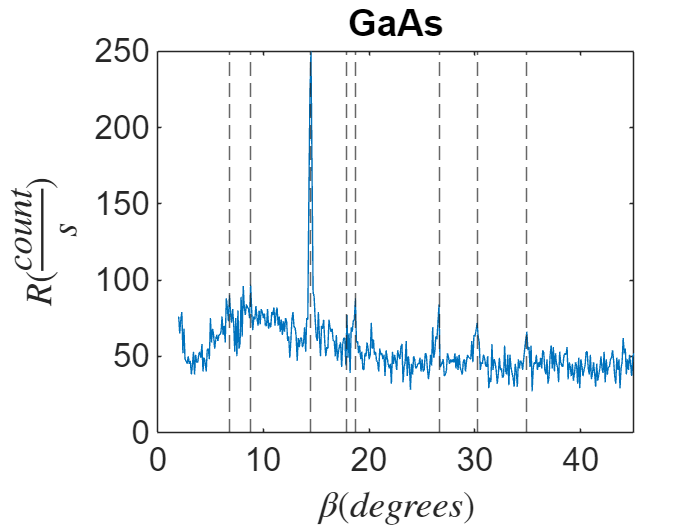

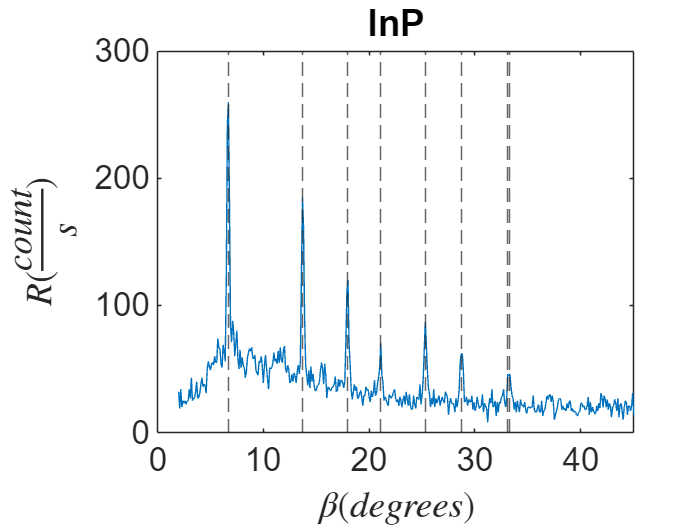

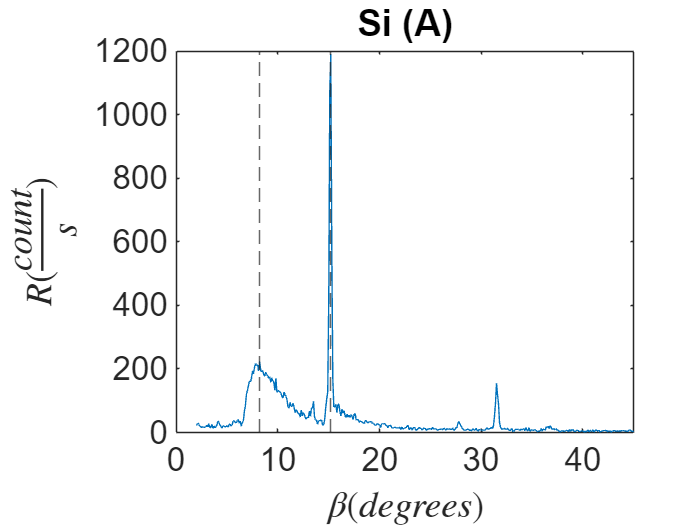

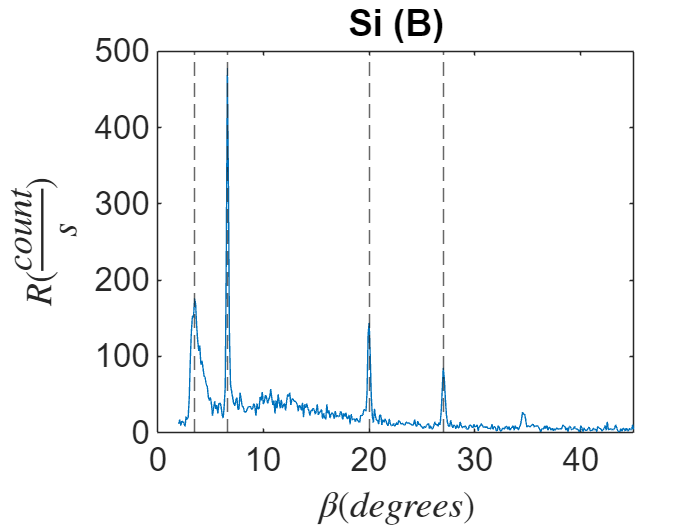

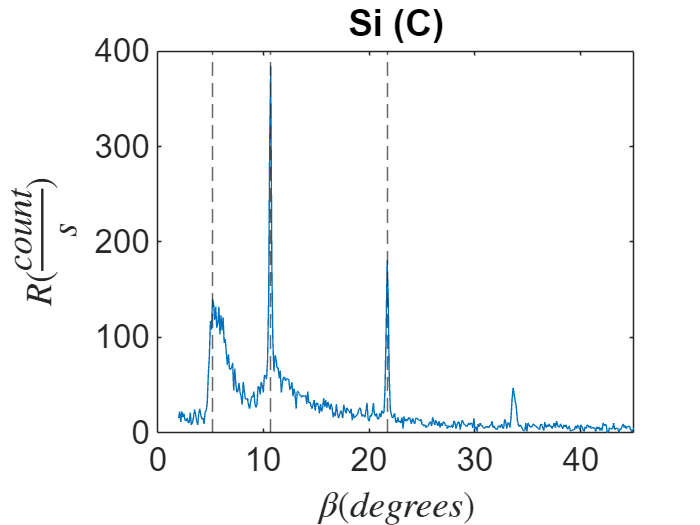

data = readmatrix('./X-ray Lab 3.xlsx','Sheet','Sheet1') ; % Import Data
cells = readcell('./X-ray Lab 3.xlsx','Sheet','Sheet1') ; % Import Data
% Initialize varibles that will hold data for each crystal
crystals = {} ;
crystals_beta = {} ;
crystals_R = {} ;
peak_angles = {} ;
crystal_name = {};
% Loop through data and parse it from the matrix
for i = 1:2:length(data(3, :))
    % add data to arrays and cell
    crystal_name= cells{1, i} ; % crystal names
    crystals{end+1} = crystal_name ; 
    crystal_beta = data(:, i) ; % crystal braggs angles
    crystals_beta{end+1} = data(:, i) ;
    crystal_R = data(:, i+1) ; % crystal rates
    crystals_R{end+1} = crystal_R ;

    % find peaks and table data
    [peak, peak_idx] = findpeaks(data(:, i+1), 'MinPeakProminence', max(data(:, i+1))*0.13) ;
    crystal_peak_angles = crystal_beta(peak_idx) ;
    peak_angles{end+1} = crystal_peak_angles ;
   
    % plot data
    figure
    plot(data(:, i), data(:, i + 1))
    title(cells(1, i))
    set(gca, 'Fontsize', 20)
    xlabel('$\beta (degrees)$', 'Interpreter', 'latex')
    ylabel('$R (\frac{count}{s})$', 'Interpreter', 'latex')
    xline(crystal_beta(peak_idx), '--')
end

T = table(crystals', peak_angles', 'VariableNames', {'Crystals', 'Bragg Angles'}) % Table for all peak angles found

T = 8×2 table
     Crystals     Bragg Angles
    __________    ____________

    {'KBr'   }    {3×1 double}
    {'LiF'   }    {2×1 double}
    {'NaCl'  }    {3×1 double}
    {'GaAs'  }    {8×1 double}
    {'InP'   }    {8×1 double}
    {'Si (A)'}    {2×1 double}
    {'Si (B)'}    {4×1 double}
    {'Si (C)'}    {3×1 double}


## Part 2: Data Parsing

Here we find the sigmas of each peak shown in the data above and use those peaks and sigmas to compare with the predicted data from the pre-lab. Then we find the lattice constants along with the uncertainities.

% Finding FWHM to find sigmas of each peak
peak_angle_sigmas = {} ; % Initialize cell array to hold sigmas
% Loop through each crystal
for i = 1:length(crystals_R)
    sigmas = [] ; % Initialize an array for the sigmas of the peak of one crystal
    % Loop through peak angles for the crystal
    for j = 1:length(peak_angles{i})
        peak_angle = peak_angles{i}(j) ; % extract peak angle
        HMidx = find(crystals_beta{i} == peak_angle) ; % find idx for the peak
        HM = crystals_R{i}(HMidx) / 2 ; % extract half of the peak
        chunk = crystals_R{i}(HMidx-10:HMidx+10) ; % Chunk data to localize the peak
        chunk_idx1 = find(chunk > HM, 1) ; % find the idx for one side of the FWHM
        chunk_idx2 = find(chunk > HM, 1, 'last') ; % find other
        idx1 = HMidx - 9 + chunk_idx1 ; % Find idx of the FWHM in terms of the whole spectra
        idx2 = HMidx - 9 + chunk_idx2 ; % Find other
        B1 = crystals_beta{i}(idx1) ; % Find degrees at that idx
        B2 = crystals_beta{i}(idx2) ; % Find other
        FW = B2 - B1 ; % Find full width at half mean
        sigma = FW / (2*sqrt(2*log(2))) ; % find sigma as half of that width
        sigmas(end+1) = sigma ; % add that sigma to the array
    end
    peak_angle_sigmas{end+1} = sigmas ; % add that array of sigmas to cell array initialized above
end

% Check for similar angles
% Initialize a variable to store similar angles
similar = {}; 
% Initialize array of veto wavelength based on graphs above
vetoes = [peak_angles{4}(1), peak_angles{4}(2), peak_angles{4}(4), peak_angles{4}(5), peak_angles{5}(1), peak_angles{5}(end), peak_angles{6}(1)] ;
%vetoes = [] ;
% Loop through each angle in the array
for i = 1:length(bragg)
    current_angle = bragg(i);
    
    % Loop through each cell in the cell array
    for j = 1:length(peak_angles)
        sub_angles = peak_angles{j}; % Get the current sub-array of angles
        
        % Check each angle in the sub-array
        for k = 1:length(sub_angles)
            threshold = peak_angle_sigmas{j}(k) * 5 ;
            if ~ismember(sub_angles(k), vetoes)
                if abs(current_angle - sub_angles(k)) <= threshold
                    % If within threshold, add to similar variable
                    if strcmp(crystal{i}(1:2), crystals{j}(1:2)) == 1 % Check if same crystal
                        sigma_away = abs(current_angle - sub_angles(k)) / peak_angle_sigmas{j}(k) ;
                        similar{end + 1} = {crystal{i}, current_angle, crystals{j} sub_angles(k), wavelength_arr(i), n_arr(i), sigma_away, peak_angle_sigmas{j}(k), hlk{i}, '', '', '', '', d_arr(i), a_arr(i)};
                    end
                end
            end
        end
    end
end


% Finding d
for i = 1:length(similar)
    d_sigma = sqrt((-cos(similar{i}{4})*similar{i}{5}*similar{i}{6} / (sin(similar{i}{4})^2*2))^2*similar{i}{8}) ;
    d = similar{i}{6}*similar{i}{5} / (2*sind(similar{i}{4})) ;
    a_sigma = sqrt(sum(similar{i}{9}))*d_sigma ;
    a = d*sqrt(sum(similar{i}{9})) ;
    similar{i}{10} = d ;
    similar{i}{11} = d_sigma ;
    similar{i}{12} = a ;
    similar{i}{13} = a_sigma ;
end
% Display the similar pairs
names = {} ;
found_bragg = {} ;
pred_bragg = {} ;
pred_wavelength = {} ;
pred_mode = {} ;
found_sigma = {} ;
found_sigma_away = {};
pred_hlk = {} ;
found_d = {} ;
found_d_sigma = {} ;
pred_d = {} ;
found_a = {} ;
found_a_sigma = {} ;
pred_a = {} ;
sigma_away_d = {} ;
sigma_away_a = {} ;
names_2 = {} ;
for i = 1:length(similar)
    names{end+1} = similar{i}{1} ;
    names_2{end+1} = similar{i}{3} ;
    found_bragg{end+1} = similar{i}{4} ;
    pred_bragg{end+1} = similar{i}{2} ;
    pred_wavelength{end+1} = similar{i}{5} ;
    pred_mode{end+1} = similar{i}{6} ;
    found_sigma{end+1} = similar{i}{8} ;
    found_sigma_away{end+1} = similar{i}{7} ;
    pred_hlk{end+1} = similar{i}{9} ;
    found_d{end+1} = similar{i}{10} ;
    found_d_sigma{end+1} = similar{i}{11} ;
    found_a{end+1} = similar{i}{12} ;
    found_a_sigma{end+1} = similar{i}{13} ;
    pred_d{end+1} = similar{i}{14} ;
    pred_a{end+1} = similar{i}{15} ;
    sigma_away_d{end+1} = abs(similar{i}{14} - similar{i}{10}) / similar{i}{11} ;
    sigma_away_a{end+1} = abs(similar{i}{15} - similar{i}{12}) / similar{i}{13} ;
end
T_similar = table(names', names_2', pred_bragg', found_bragg', pred_wavelength', pred_mode', found_sigma', found_sigma_away', pred_hlk', found_d', found_d_sigma', pred_d', sigma_away_d', found_a', found_a_sigma', pred_a', sigma_away_a', 'VariableNames', {'Crystal Predicted', 'Crystal Measured', 'Predicted Angle', 'Found angle', 'Wavelength', 'Mode', 'Sigma', 'Sigma Away', 'hlk', 'Found d', 'sigma d', 'Predicted d', 'Sigma away for d', 'Found a', 'sigma a', 'Predicted a', 'Sigma away for a'})

T_similar = 26×17 table
    Crystal Predicted    Crystal Measured    Predicted Angle    Found angle    Wavelength    Mode       Sigma       Sigma Away       hlk         Found d        sigma d       Predicted d    Sigma away for d      Found a        sigma a       Predicted a    Sigma away for a
    _________________    ________________    _______________    ___________    __________    _____    __________    __________    _________    ___________    ____________    ___________    ______________

## Determining Avogadro's Number


$$\begin{array}{l}
\rho_{\textrm{NaCl}} =2\ldotp 165\;\frac{g}{{\textrm{cm}}^2 }\\
\rho_{\textrm{KBr}} =2\ldotp 745\frac{g}{{\textrm{cm}}^2 }\\
\rho_{\textrm{LiF}} =2\ldotp 635\frac{g}{{\textrm{cm}}^2 }
\end{array}$$



$$\begin{array}{l}
M_{\textrm{NaCl}} =58\ldotp 44\frac{g}{\textrm{mol}}\\
M_{\textrm{KBr}} =119\ldotp 00\frac{g}{\textrm{mol}}\\
M_{\textrm{LiF}} =25\ldotp 94\frac{g}{\textrm{mol}}
\end{array}$$



$$V_m =\frac{M}{\rho }\left(\frac{{\textrm{cm}}^3 }{\textrm{mol}}\right)$$



$$V_{\textrm{per}\;\textrm{ion}} =\frac{a^3 }{2}\left({\overset{\circ }{A} }^3 \right)$$



$$\begin{array}{l}
N_{\textrm{ion}} =\frac{1}{V_{\textrm{per}\;\textrm{ion}} }\left(\frac{1}{{\overset{\circ }{A} }^3 }\right)\\
N_A =N_{\textrm{ion}} V_m =\frac{2M}{\rho a^3 }\;\left(\frac{1}{\textrm{mol}}\right),\;\textrm{where}\;N_{A\;} \textrm{is}\;{\textrm{Avogadro}}^{\prime } s\;\textrm{Number}\\
\sigma_{N_A } =\sqrt{{\left(\frac{\partial }{\partial a}\left(\frac{2M}{\rho a^3 }\right)\right)}^2 \sigma_a^2 }=\sqrt{{\left(-\frac{6M}{\rho a^4 }\right)}^2 \sigma_a^2 }=\sqrt{\frac{36M^2 }{\rho^2 a^8 }\sigma_a^2 }
\end{array}$$


Using the densities and molar masses of each crystal we can derive an equation to find Avogadro's number based on the lattice constant a. Finding the molar volume and multiplying it by number of ions per volume will lead to Avogadro's number.

% Initialize initial varibles
rho_NaCl = 2.165 ; % density of NaCl (g/cm^3)
rho_KBr = 2.745 ; % density of KBr/cm^3)
rho_LiF = 2.635 ; % density of LiF (g/cm^3)
M_NaCl = 58.44 ; % mass per mol of NaCl (g/mol)
M_KBr = 119 ; % mass per mol of KBr (g/mol)
M_LiF = 25.94 ; % mass per mol of LiF (g/mol)
% Loop through results and average lattice constant and their sigmas
a_NaCl_arr = [] ;
a_NaCl_sigma_arr = [] ;
a_KBr_arr = [] ;
a_KBr_sigma_arr = [] ;
a_LiF_arr = [] ;
a_LiF_sigma_arr = [] ;
for i = 1:length(similar)
    if strcmp(similar{i}{1}, 'NaCl') == 1
        a_NaCl_arr(end+1) = similar{i}{12} ;
        a_NaCl_sigma_arr(end+1) = similar{i}{13} ;
    elseif strcmp(similar{i}{1}, 'KBr') == 1
        a_KBr_arr(end+1) = similar{i}{12} ;
        a_KBr_sigma_arr(end+1) = similar{i}{13} ;
    elseif strcmp(similar{i}{1}, 'LiF') == 1
        a_LiF_arr(end+1) = similar{i}{12} ;
        a_LiF_sigma_arr(end+1) = similar{i}{13} ;
    end
end
a_NaCl = mean(a_NaCl_arr) * 1e-8 ; % lattice constant for NaCl (cm)
a_NaCl_sigma = mean(a_NaCl_sigma_arr) * 1e-8 ; % uncertainity for lattice constant
a_KBr = mean(a_KBr_arr) * 1e-8; % lattice constant for KBr (cm)
a_KBr_sigma = mean(a_KBr_sigma_arr) * 1e-8 ;% uncertainity for lattice constant
a_LiF = mean(a_LiF_arr) * 1e-8 ; % lattice constant for LiF (cm)
a_LiF_sigma = mean(a_LiF_sigma_arr) * 1e-8 ; % uncertainity for lattice constant
% Find Avogadro's Number and uncertainity
N = 6.022e23 ;
N_NaCl = (2*M_NaCl) / (rho_NaCl*a_NaCl^3)

N_NaCl = 1.6261e+23

N_NaCl_sigma = sqrt(((36*M_NaCl^2)/(rho_NaCl^2*a_NaCl^8))*a_NaCl_sigma^2) ;
NaCl_sigma_away = abs(N - N_NaCl) / N_NaCl_sigma

NaCl_sigma_away = 12.9484

N_KBr = (2*M_KBr) / (rho_KBr*a_KBr^3)

N_KBr = 1.5967e+23

N_KBr_sigma = sqrt(((36*M_KBr^2)/(rho_KBr^2*a_KBr^8))*a_KBr_sigma^2) ;
KBr_sigma_away = abs(N - N_KBr) / N_KBr_sigma

KBr_sigma_away = 0.1004

N_LiF = (2*M_LiF) / (rho_LiF*a_LiF^3)

N_LiF = 3.0369e+23

N_LiF_sigma = sqrt(((36*M_LiF^2)/(rho_LiF^2*a_LiF^8))*a_LiF_sigma^2) ;
LiF_sigma_away = abs(N - N_LiF) / N_LiF_sigma

LiF_sigma_away = 5.8037

**Analysis:**

The data shows the that our predicted avogadro's number is not very accurate with the number found from LiF being the closest at 5.8 sigma away from the actual number. All the predicted values are on or close to the same magnitude as Avogadro's number which is a good sign. Reason's for this discrepancy could be because of the magnitude of Avogadro's number itself being so high, any error in the taking of data would be magnified. A way to combat this would be to lower delta_bragg so that there are more data points to work with.

## Determining the Lattice Constant and Orientation of Si

For this part, all we need to do is compare the data above in the table T_similar as well as average the lattice constants for each and their uncertainites. Below we see,

Si(A) is Si(100) as that is the only crystal with a similar reflection

Si(C) is Si(110) as that is the only crystal with similar reflections

Si(B) is Si(111) as there are similarities between Si(B) and Si(C) and Si(111) but we already state Si(C) as Si(110)

T_similar

T_similar = 26×17 table
    Crystal Predicted    Crystal Measured    Predicted Angle    Found angle    Wavelength    Mode       Sigma       Sigma Away       hlk         Found d        sigma d       Predicted d    Sigma away for d      Found a        sigma a       Predicted a    Sigma away for a
    _________________    ________________    _______________    ___________    __________    _____    __________    __________    _________    ___________    ____________    ___________    ______________

a_Si_arr = [] ;
a_Si_sigma_arr = [] ;
for i = 1:length(similar)
    if strcmp(similar{i}{1}(1:2), 'Si') == 1
        a_Si_arr(end+1) = similar{i}{12} ;
        a_Si_sigma_arr(end+1) = similar{i}{13} ;
    end
end
actual_a_Si = 5.43 ;
a_Si = mean(a_Si_arr)

a_Si = 6.0278

a_Si_sigma = mean(a_Si_sigma_arr) 

a_Si_sigma = 1.4568

a_Si_sigma_away = abs(actual_a_Si - a_Si) / a_Si_sigma

a_Si_sigma_away = 0.4104

**Analysis:**

This result is very good. For the lattice constant we got a value of $a=6\ldotp 03\pm 1\ldotp 5\;\mathrm{angstroms}$ and being only 0.41 sigma away from the actual lattice constant 5.43 angstroms. The uncertainity for out found value is quite high, which could lead to poor results. The reason for this could be because of the technique we employed to find the uncertainity which is by averaging all of the uncertainites we measured. 

## Lattice Constant and Extinction of GaAs and InP

For this part we need to look at the table able and compare. Here we see reflections at 400 and 800 for GaAs, as for the 200 reflection, the lab manual didn't specify that as a accepted reflection so it was not detected. For InP we see reflections at 200, 400, 600, and 800 verifying those extinctions.